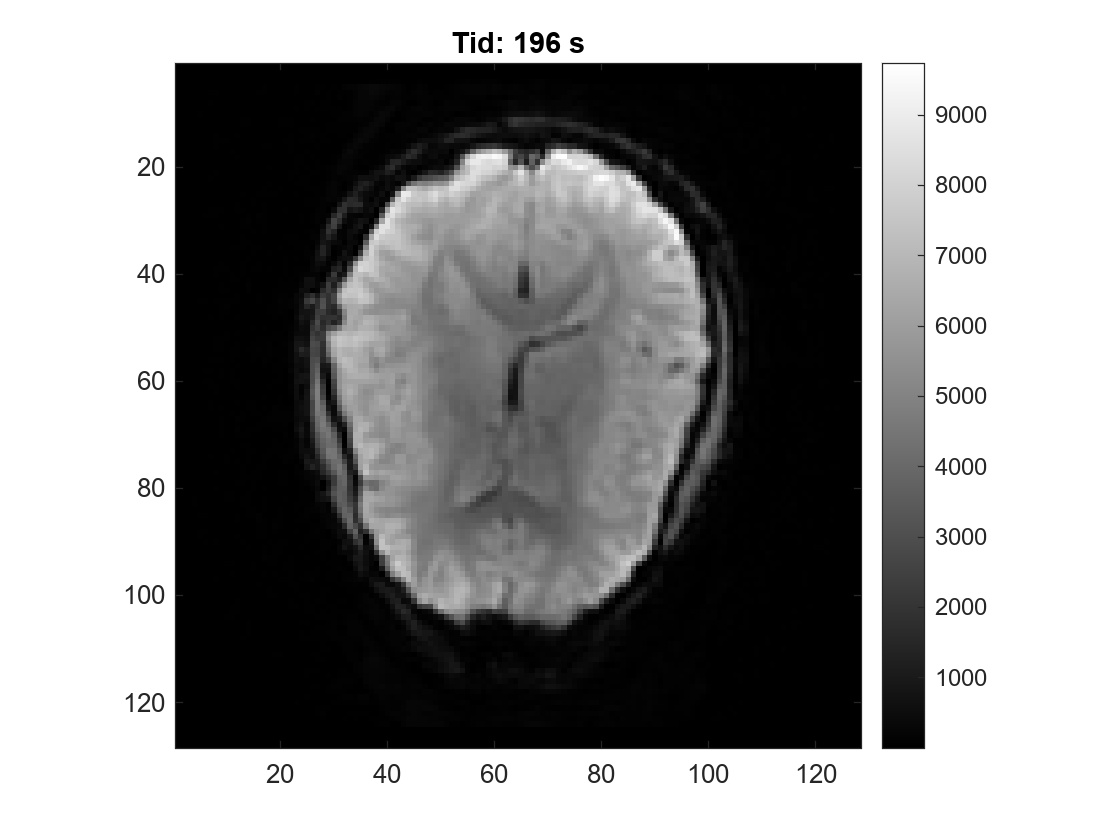

%% Load raw k-space data
load('Data/rawData.mat');  % justera sökvägen om det behövs

%% Skapa 3D-bilder via iFFT
% Antag att rawData heter 'kSpace' i filen och har dimensioner [X Y Z T]
% X, Y, Z = rumsliga dimensioner, T = antal tidssteg (160)

numTimepoints = size(kSpace,4);       % 160
img = zeros(size(kSpace));            % 4D-array för bilder (X x Y x Z x T)

for t = 1:numTimepoints
    k0 = kSpace(:,:,:,t);             % plocka ut k-space vid tid t
    img(:,:,:,t) = abs(fftshift(ifftn(ifftshift(k0))));  % iFFT och absolutvärde
end

%% Visa mittsnitt i z-led som animation
z_mid = round(size(img,3)/2);         % mitt i z-led

figure;
for t = 1:numTimepoints
    imagesc(img(:,:,z_mid,t));
    colormap gray; 
    axis image; 
    colorbar;
    title(['Tid: ' num2str(t*2) ' s']);  % 2 s per bild
    pause(0.05);  % justera hastighet på animationen
end